% frequency of message signal in Hz
fm = 10;

%frequency of carrier signal in Hz
fc = 100;

t = linspace(-0.125, 0.125, 1000);

%message signal
m = 0.5*cos(2*pi*fm*t);

%modulated signal/signal after Modulation
f = m.*cos(2*pi*fc*t);

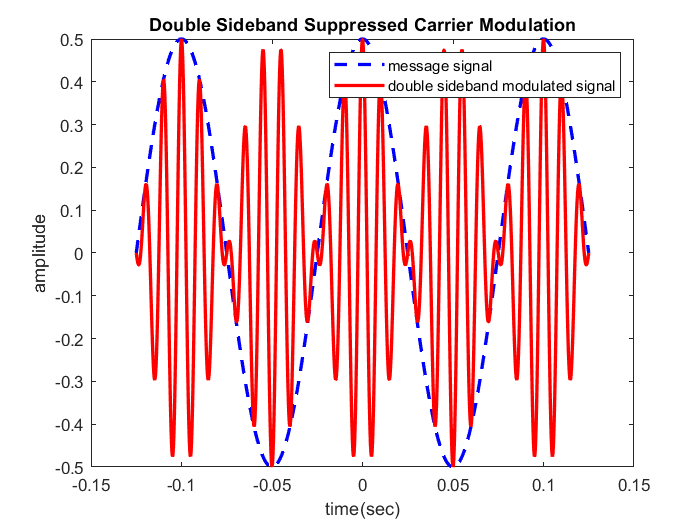


%plotting message signal and modulated signal
plot(t, m, "b--", "LineWidth", 2)
hold on
plot(t, f, "r-", "LineWidth", 2)
xlabel("time(sec)")
ylabel("amplitude")
title("Double Sideband Suppressed Carrier Modulation")
legend("message signal", "double sideband modulated signal")
hold off

%calculating Hilbert Tranform of message signal
mh = imag(hilbert(m));

%Upper Sideband Signal
ssb = m.*cos(2*pi*fc*t) - mh.*sin(2*pi*fc*t);


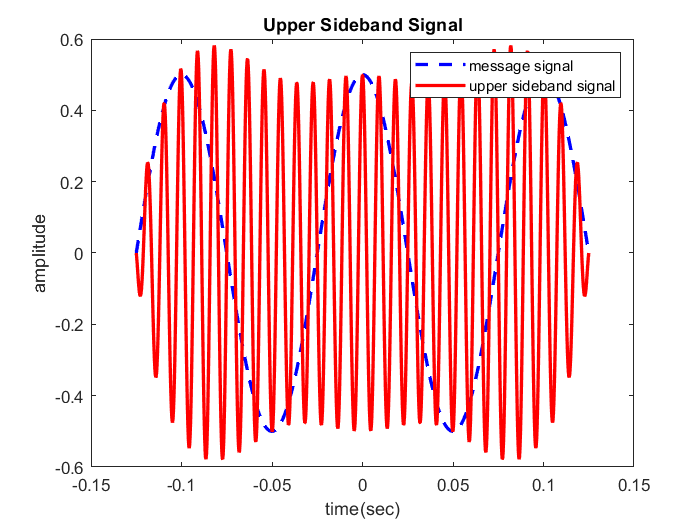

%plotting message signal and upper sideband signal
plot(t, m, "b--", "LineWidth", 2)
hold on
plot(t, ssb, "r-", "LineWidth", 2)
xlabel("time(sec)")
ylabel("amplitude")
title("Upper Sideband Signal")
legend("message signal", "upper sideband signal")
hold off

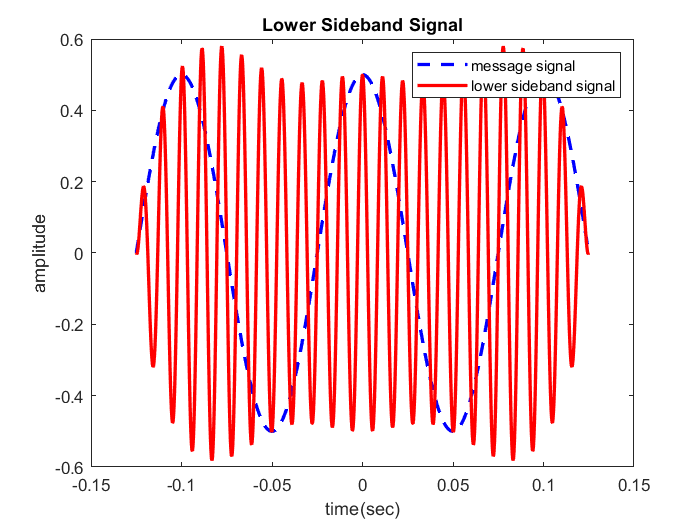

%plotting message signal and lower sideband signal
slsb = m.*cos(2*pi*fc*t) + mh.*sin(2*pi*fc*t);
plot(t, m, "b--", "LineWidth", 2)
hold on
plot(t, slsb, "r-", "LineWidth", 2)
xlabel("time(sec)")
ylabel("amplitude")
title("Lower Sideband Signal")
legend("message signal", "lower sideband signal")
hold off

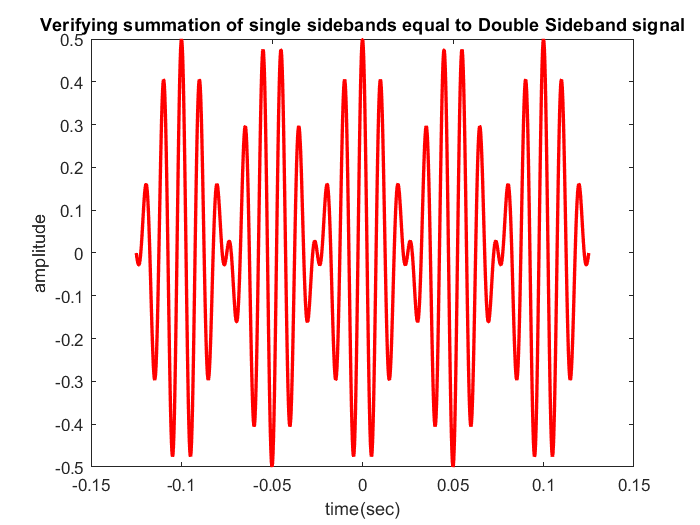

%verifying that summation of upper sideband and lower sideband is equal to
%double side band modulated signal
plot(t, (ssb+slsb)/2, "r-", "LineWidth", 2)
xlabel("time(sec)")
ylabel("amplitude")
title("Verifying summation of single sidebands equal to Double Sideband signal")